## Import and organize data

% Read in data
data = readtable("Balloon Prelab Data 2020.xlsx");


% Remove unnecessary data
data.Var1 = [];
data(4:5, :) = [];

% Change variable names to be more user-friendly
newVarNames = {'BalloonNumber', 'BalloonMass', 'StringMass', 'AdditionalMass', 'PayloadMass', 'PILOTTemp', 'PILOTPressure', 'BalloonDiameter', 'MaxBalloonThickness', 'WaterHeightDisplacement', 'TankLength', 'TankWidth'};
data.Properties.VariableNames = newVarNames;

% Sort data by ascending balloon mass (to help with graphs)
% data = sortrows(data, 'BalloonMass');

% Convert various data types to number values
data.TankLength = str2num(cell2mat(data.TankLength));
data.WaterHeightDisplacement = [98.0, 105.0,96.0]';
data.BalloonDiameter = str2num(cell2mat(data.BalloonDiameter));
data.PILOTPressure = str2num(cell2mat(data.PILOTPressure));
data.PILOTTemp = str2num(cell2mat(data.PILOTTemp));

% Add new variables based on existing data
data.TankArea = data.TankLength .* data.TankWidth; % Tank area in in^2
data.TotalMass = data.BalloonMass + data.PayloadMass + data.StringMass; % Tank mass in g
data.BalloonVolume = ( data.TankArea / 1550) .* (data.WaterHeightDisplacement / 1000); % Balloon volume in m^3
data.PILOTTempK = (data.PILOTTemp + 459.67) .* (5/9); % Pilot temp in Kelvin
data.PILOTPressurePa = data.PILOTPressure .* 100; % Pilot pressure in Pa

% Display table
data

data = 3×17 table
    BalloonNumber    BalloonMass    StringMass    AdditionalMass    PayloadMass    PILOTTemp    PILOTPressure    BalloonDiameter    MaxBalloonThickness    WaterHeightDisplacement    TankLength    TankWidth    TankArea    TotalMass    BalloonVolume    PILOTTempK    PILOTPressurePa
    _____________    ___________    __________    ______________    ___________    _________    _____________    _______________    ___________________    _______________________    __________    _________   

## Create graph(s)

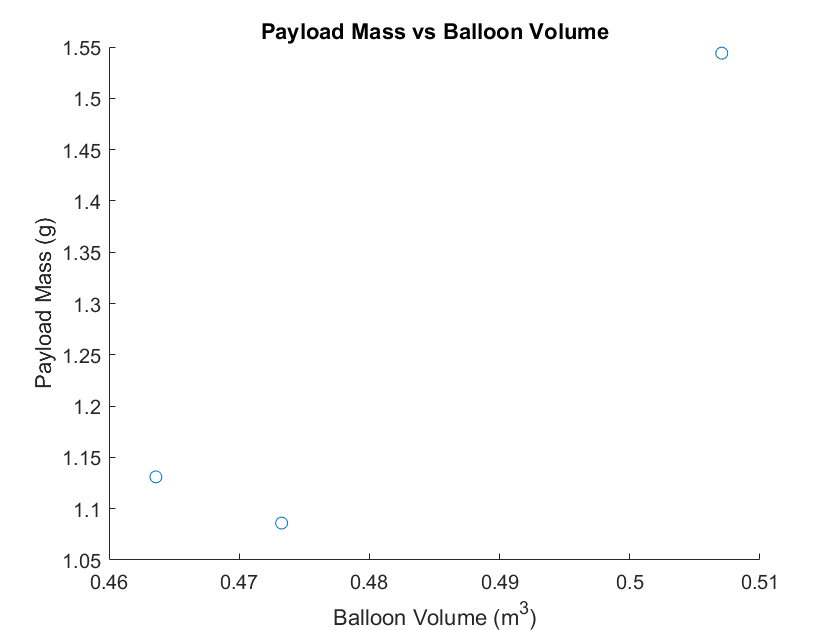

% Preliminary plot of payload mass vs balloon volume
scatter(data.BalloonVolume, data.PayloadMass)
title("Payload Mass vs Balloon Volume");
xlabel("Balloon Volume (m^3)");
ylabel("Payload Mass (g)");

## Experiment analysis

% Find force caused by gravity
forceGrav = data.TotalMass .* 9.81 % Force of gravity in m/s^2

forceGrav =   104.5256
  108.8616
  105.3888



% Find buoyancy force
%    F_B = rho_f * gravity * volume
%    rho_f = F_B / (gravity * volume)
forceBuoy = forceGrav % Buoyant force is equal to force of gravity when neutrally buoyant

forceBuoy =   104.5256
  108.8616
  105.3888


rho_f = forceBuoy ./ (9.8 .* data.BalloonVolume)

rho_f =    22.5371
   21.9072
   23.1966




% Estimate required mass of gas
% P = dens * R * temp
% Density = Pressure / (R * temp)
R = 2.0769; % Universal gas constant in kJ / kg*K
densityHe = data.PILOTPressurePa ./ (R .* data.PILOTPressure) % Density of air in g/m^3

densityHe =    48.1487
   48.1487
   48.1487


massHe = densityHe .* data.BalloonVolume % Mass of He in g

massHe =    22.7868
   24.4144
   22.3218



% Ratio massHe to mass held
massRatio = massHe ./ data.PayloadMass

massRatio =    20.9823
   15.8125
   19.7363


avgMassRatio = mean(massRatio)

avgMassRatio = 18.8437